# Convolution Coding for Rate=1/3 and Kc=4


EbByNodb = 0:0.5:10;

R = 1/3;
k = 1;
n = 3;
kc = 4; 

% Generating Practical_error and Theoratical_error matrices :
practical_error_Hard = zeros(1,length(EbByNodb));
practical_error_Soft = zeros(1, length(EbByNodb));
theoretical_error = zeros(1,length(EbByNodb));


Index = 1;
Index1 = 1;

N = 5000;
for j = EbByNodb
    EbByNo = 10^(j/10);
    std_dev = sqrt (1/(2*R*EbByNo));

    %BER = 0.5*erfc(1/((sqrt(2)*std_dev)) );
    %BER = 0.5*erfc( sqrt(EbByNo) );
    BER = 0.5 * erfc(sqrt(1 * EbByNo));

    No_of_errors_Hard = 0;
    No_of_errors_Soft = 0;

    i = 1;
    while i <= N

        %Generate Random msg
        message = randi ([0 1],1,10); 
        message = [message zeros(1,kc-1)];
        %disp(msg);
        
        enc_array = Encoder(message);  % Encoding the msg
        %disp(enc_array);
        
        modulated_msg = Modulation(enc_array , std_dev);  %Modulating msg through BPSK modulation
        %disp(modulated_msg);
        
        demodulated_msg = modulated_msg < 0;
        %disp(demodulated_msg);

        % Call Viterbi function
        decoded_msg_Hard = Hard_Decoder(demodulated_msg);
        decoded_msg_Soft = Soft_Decoder(modulated_msg);
        %disp(decoded_msg);

        No_of_errors_Hard = No_of_errors_Hard + sum(message ~= decoded_msg_Hard);
        No_of_errors_Soft = No_of_errors_Soft + sum(message ~= decoded_msg_Soft);
        i = i + 1;
    end 

    practical_error_Hard(Index) = (No_of_errors_Hard / (N*length(message)));  % Calculating the practical error through hard decision decoding
    practical_error_Soft(Index) = (No_of_errors_Soft / (N*length(message)));  % Calculating the practical error through soft decision decoding
    theoretical_error(1,Index1) = BER;  % Theoratical error from the formula of BER
    Index = Index + 1;
    Index1 = Index1 + 1;
end

practical_error_Soft

practical_error_Soft =     0.1611    0.1244    0.0942    0.0626    0.0445    0.0260    0.0172    0.0094    0.0048    0.0030    0.0013    0.0006    0.0004    0.0002    0.0001    0.0000         0    0.0000         0         0         0


practical_error_Hard

practical_error_Hard =     0.2157    0.1905    0.1494    0.1246    0.0988    0.0723    0.0500    0.0326    0.0212    0.0126    0.0079    0.0033    0.0016    0.0014    0.0004    0.0003    0.0002    0.0001    0.0000         0         0


theoretical_error

theoretical_error =     0.0786    0.0671    0.0563    0.0464    0.0375    0.0297    0.0229    0.0172    0.0125    0.0088    0.0060    0.0039    0.0024    0.0014    0.0008    0.0004    0.0002    0.0001    0.0000    0.0000    0.0000


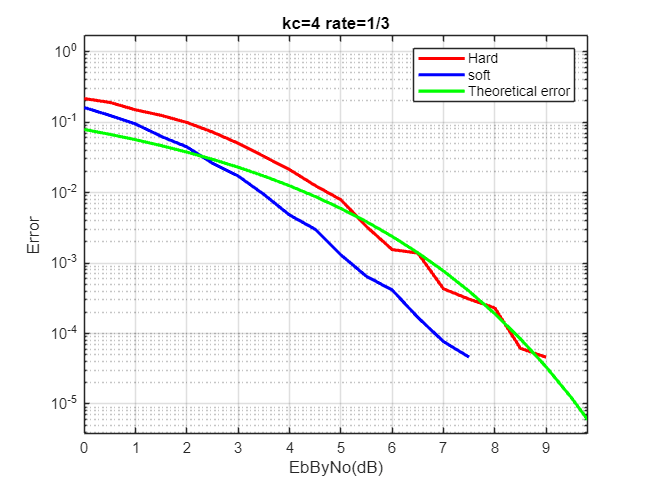

% Ploting the Graph From our Results
semilogy(EbByNodb, practical_error_Hard, 'r-', 'LineWidth', 2.0);
hold on;
semilogy(EbByNodb, practical_error_Soft, 'b-', 'LineWidth', 2.0);
semilogy(EbByNodb, theoretical_error, 'g-', 'LineWidth', 2.0);
legend('Hard','soft', 'Theoretical error');
title('kc=4 rate=1/3');
grid on
xlabel('EbByNo(dB)');
ylabel('Error');
hold off;

xlim([0.1 9.9])
ylim([0.00 0.90])

xlim([-0.0 9.8])
ylim([0.00 1.67])

## Encoding Function


function observe = Encoder(input)

    % Initialize shift register
    g1 = [1 0 1 1]; % Generator polynomial for output bit 1
    g2 = [1 1 0 1]; % Generator polynomial for output bit 2
    g3 = [1 1 1 1]; % Generator polynomial for output bit 3

    observe = zeros(1, length(input) * 3);
    state = [0 0 0];
    observe_index = 1;
    %disp(observe);

    % Iterate over input sequence
    for i = 1:length(input)

        % Update the state of the encoder

        reg = [input(i) state];
        state = [input(i) state(1:2)];

        % Encode the input message using the generator polynomials

        output1 = mod(reg*g1', 2);
        output2 = mod(reg*g2', 2);
        output3 = mod(reg*g3', 2);

        % Store encoded bits in 1D array

        observe(observe_index) = output1;
        observe(observe_index + 1) = output2;
        observe(observe_index + 2) = output3;
        observe_index = observe_index + 3;
    end
    
end



## Modulation Function


function modulated_opeartion = Modulation(encoded_msg,std_dev)
     % BPSK modulation
     s = 1 - 2 * encoded_msg; 
     modulated_opeartion = s + std_dev * randn(1, length(encoded_msg));
end


## Hamming Distance calculator Function


function dist = Hamming_Distance(x,y,w,z,p,q)
    dist = xor(x,z)+xor(y,p)+xor(w,q);
end



## Euclidean distance calculator function



function dist = Euclidean_Distance(x,y,w,z,p,q)
    dist = sqrt((x-z)^2+(y-p)^2+(w-q)^2);
end



## Hard Decision Decoding Function


function decoded_msg_Hard = Hard_Decoder(observed)

 st_metric = struct('zero', 0, 'one', 0, 'two', 0, 'three', 0 , 'four', 0 , 'five', 0 , 'six', 0 , 'seven', 0);
 state_machine = struct( ...
            'zero',... 
            struct('b1', struct('out_b', [1 1 1], 'prev_st', 'one', 'input_b',0), ...
                      'b2', struct('out_b', [0 0 0], 'prev_st', 'zero', 'input_b',0)), ... 
            'one',... 
            struct('b1', struct('out_b', [0 1 0], 'prev_st', 'three', 'input_b',0), ...
                      'b2', struct('out_b', [1 0 1], 'prev_st', 'two', 'input_b',0)), ...
            'two', ...
            struct('b1', struct('out_b', [0 1 1], 'prev_st', 'four', 'input_b',0), ...
                      'b2', struct('out_b', [1 0 0], 'prev_st', 'five', 'input_b',0)), ... 
            'three', ...
            struct('b1', struct('out_b', [1 1 0], 'prev_st', 'six', 'input_b',0), ...
                      'b2', struct('out_b', [0 0 1], 'prev_st', 'seven', 'input_b',0)), ... 
            'four',...
            struct('b1', struct('out_b', [1 1 1], 'prev_st', 'zero', 'input_b',1), ...
                      'b2', struct('out_b', [0 0 0], 'prev_st', 'one', 'input_b',1)), ...
            'five',...
            struct('b1', struct('out_b', [1 0 1], 'prev_st', 'three','input_b', 1), ...
                      'b2', struct('out_b', [0 1 0], 'prev_st', 'two', 'input_b',1)), ...
            'six',...
            struct('b1', struct('out_b', [1 0 0], 'prev_st', 'four', 'input_b',1), ...
                      'b2', struct('out_b', [0 1 1], 'prev_st', 'five', 'input_b',1)), ...
            'seven',...
            struct('b1', struct('out_b', [0 0 1], 'prev_st', 'six','input_b', 1), ...
                      'b2', struct('out_b',[1 1 0], 'prev_st', 'seven', 'input_b',1)));

 % Trellis structure
 decoded_msg_Hard = [];
 mp = cell(1, length(observed)/3 + 1);
 mp{1} = containers.Map();

 for i = fieldnames(state_machine)'
   mp{1}(i{1}) = struct('metric', st_metric.(i{1}));
 end

 for j = 1:length(observed)/3
    mp{j + 1} = containers.Map();

     for i = fieldnames(state_machine)'
         % Check for smallest bit difference from possible previous paths, adding with previous metric
        
         previous_state_1 = state_machine.(i{1}).b1.prev_st;
         first_branch_metric = mp{j}(previous_state_1).metric + (Hamming_Distance(state_machine.(i{1}).b1.out_b(1),state_machine.(i{1}).b1.out_b(2),state_machine.(i{1}).b1.out_b(3),observed(3*j-2),observed(3*j-1),observed(3*j)));
        
         previous_state_2 = state_machine.(i{1}).b2.prev_st;
         second_branch_metric = mp{j}(previous_state_2).metric + (Hamming_Distance(state_machine.(i{1}).b2.out_b(1),state_machine.(i{1}).b2.out_b(2),state_machine.(i{1}).b2.out_b(3),observed(3*j-2),observed(3*j-1),observed(3*j)));
        
         if first_branch_metric > second_branch_metric
             mp{j + 1}(i{1}) = struct('metric', second_branch_metric,'branch', 'b2');
         
         else
             mp{j + 1}(i{1}) = struct('metric', first_branch_metric, 'branch','b1');
         end
     end
 end


 % Traceback the path on smaller metric on last trellis column

 smaller = min(cellfun(@(x) x.metric, mp{end}.values));
 for i = fieldnames(state_machine)'

     if mp{end}(i{1}).metric == smaller
         source_state = i{1};

         for t = length(observed)/3:-1:1

             branch = mp{t + 1}(source_state).branch;
             % Correcting the index
             decoded_msg_Hard = [state_machine.(source_state).(branch).input_b,decoded_msg_Hard]; 
             source_state = state_machine.(source_state).(branch).prev_st;

         end
         %decoded_msg_Hard
         break;
     end
 end
end




## Soft Decision Decoding



function decoded_msg_Soft = Soft_Decoder(observed)


st_metric = struct('zero', 0, 'one', 0, 'two', 0, 'three', 0 , 'four', 0 , 'five', 0 , 'six', 0 , 'seven', 0);
state_machine = struct( ...
            'zero',... 
            struct('b1', struct('out_b', [-1 -1 -1], 'prev_st', 'one', 'input_b',0), ...
                      'b2', struct('out_b', [1 1 1], 'prev_st', 'zero', 'input_b',0)), ... 
            'one',... 
            struct('b1', struct('out_b', [1 -1 1], 'prev_st', 'three', 'input_b',0), ...
                      'b2', struct('out_b', [-1 1 -1], 'prev_st', 'two', 'input_b',0)), ...
            'two', ...
            struct('b1', struct('out_b', [1 -1 -1], 'prev_st', 'four', 'input_b',0), ...
                      'b2', struct('out_b', [-1 1 1], 'prev_st', 'five', 'input_b',0)), ... 
            'three', ...
            struct('b1', struct('out_b', [-1 -1 1], 'prev_st', 'six', 'input_b',0), ...
                      'b2', struct('out_b', [1 1 -1], 'prev_st', 'seven', 'input_b',0)), ... 
            'four',...
            struct('b1', struct('out_b', [-1 -1 -1], 'prev_st', 'zero', 'input_b',1), ...
                      'b2', struct('out_b', [1 1 1], 'prev_st', 'one', 'input_b',1)), ...
            'five',...
            struct('b1', struct('out_b', [-1 1 -1], 'prev_st', 'three','input_b', 1), ...
                      'b2', struct('out_b', [1 -1 1], 'prev_st', 'two', 'input_b',1)), ...
            'six',...
            struct('b1', struct('out_b', [-1 1 1], 'prev_st', 'four', 'input_b',1), ...
                      'b2', struct('out_b', [1 -1 -1], 'prev_st', 'five', 'input_b',1)), ...
            'seven',...
            struct('b1', struct('out_b', [1 1 -1], 'prev_st', 'six','input_b', 1), ...
                      'b2', struct('out_b', [-1 -1 1], 'prev_st', 'seven', 'input_b',1)));

 % Trellis structure
 decoded_msg_Soft = [];
 mp = cell(1, length(observed)/3 + 1);
 mp{1} = containers.Map();

 for i = fieldnames(state_machine)'
   mp{1}(i{1}) = struct('metric', st_metric.(i{1}));
 end

 for j = 1:length(observed)/3
    mp{j + 1} = containers.Map();

     for i = fieldnames(state_machine)'
         % Check for smallest bit difference from possible previous paths, adding with previous metric
        
         previous_state_1 = state_machine.(i{1}).b1.prev_st;
         first_branch_metric = mp{j}(previous_state_1).metric + (Euclidean_Distance(state_machine.(i{1}).b1.out_b(1),state_machine.(i{1}).b1.out_b(2),state_machine.(i{1}).b1.out_b(3),observed(3*j-2),observed(3*j-1),observed(3*j)));
        
         previous_state_2 = state_machine.(i{1}).b2.prev_st;
         second_branch_metric = mp{j}(previous_state_2).metric + (Euclidean_Distance(state_machine.(i{1}).b2.out_b(1),state_machine.(i{1}).b2.out_b(2),state_machine.(i{1}).b2.out_b(3),observed(3*j-2),observed(3*j-1),observed(3*j)));
        
         if first_branch_metric > second_branch_metric
             mp{j + 1}(i{1}) = struct('metric', second_branch_metric,'branch', 'b2');
         
         else
             mp{j + 1}(i{1}) = struct('metric', first_branch_metric, 'branch','b1');
         end
     end
 end


 % Traceback the path on smaller metric on last trellis column

 smaller = min(cellfun(@(x) x.metric, mp{end}.values));
 for i = fieldnames(state_machine)'

     if mp{end}(i{1}).metric == smaller
         source_state = i{1};

         for t = length(observed)/3:-1:1

             branch = mp{t + 1}(source_state).branch;
             % Correcting the index
             decoded_msg_Soft = [state_machine.(source_state).(branch).input_b,decoded_msg_Soft]; 
             source_state = state_machine.(source_state).(branch).prev_st;

         end
         %decoded_msg_Soft
         break;
     end
 end
end



